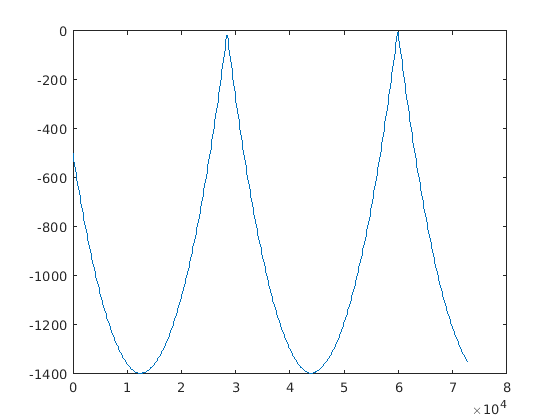

clc
clear all

% Velocity profile is constant

dt = 0.1;
deep = 3000;
lambda = 0.016;

t = [0:dt:50];

X = zeros(size(t));
X(1) = 0;

Z = zeros(size(t));
Z(1) = 500;

C = zeros(size(t));
Co = 1450;
C(1) = Co;

theta = zeros(size(t));
theta(1) = 10 * pi /180;


for i = 2:length(t)
    
    X(i) = X(i-1) + C(i-1) * dt * cos(theta(i-1));
    Z(i) = Z(i-1) + C(i-1) * dt * sin(theta(i-1));
    C(i) = Co + lambda * Z(i);
    
    K = cos(theta(i-1))*C(i)/C(i-1);
    
    if K <= 1
        
        theta(i) = sign(theta(i-1))*acos(K);
        
    else

        Z(i) = Z(i-1);
        C(i) = C(i-2);
        theta(i) = -theta(i-2);
        
    end
    
    if Z(i) < 0
        
        Z(i) = Z(i-1);
        C(i) = C(i-2);
        theta(i) = -theta(i-2);
        
    end
    
end

plot(X,-Z)

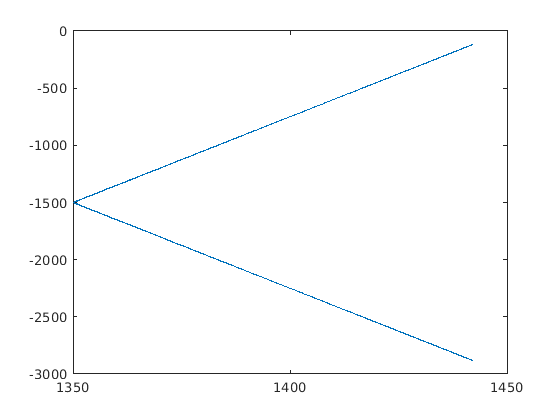

% Velocity profile negtive

dt = 0.01;
deep = 3000;
lambda_up = -0.026;
lambda_below = 0.016;

t = [0:dt:60];

X = [-10:0.1:50];

Z = zeros(size(t));
Zs = 200;
Z(1) = Zs;
Z_inv = 500;

C = zeros(size(t));
Co = 1450;
C(1) = velocity(Z(1));

theta = zeros(size(t));
theta(1) = 5 * pi /180;



for i = 2:length(t)
    
    X(i) = X(i-1) + C(i-1) * dt * cos(theta(i-1));
    Z(i) = Z(i-1) + C(i-1) * dt * sin(theta(i-1));
    C(i) = velocity(Z(i));
    
    K = cos(theta(i-1))*C(i)/C(i-1);
    
    if K <= 1
        
        theta(i) = sign(theta(i-1))*acos(K);
        
    else

        Z(i) = Z(i-1);
        C(i) = C(i-2);
        theta(i) = -theta(i-2);
        
    end
    
    if Z(i) <= 0
        
        Z(i) = Z(i-1);
        C(i) = C(i-2);
        theta(i) = -theta(i-2);
        
    elseif Z(i) >= deep  
        Z(i) = Z(i-1);
        C(i) = C(i-2);
        theta(i) = -theta(i-2);
    end

end

plot(C,-Z)

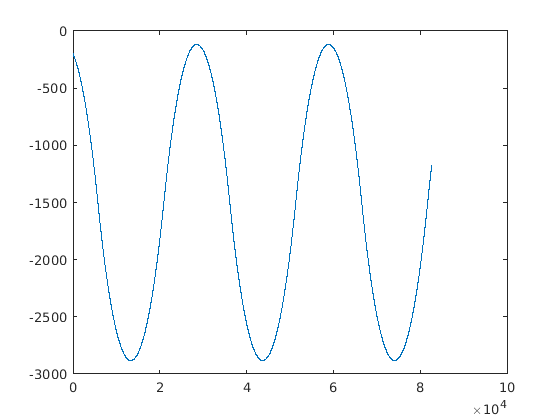

plot(X,-Z)

function C = velocity(z)
    z1 = 1500; % Z_inv
    c0 = 1450; % surface speed
    c1 = 1350; % speed Z_inv
    z0 =0;     % Z surface
    
    if z<z1
        m = (c1-c0)/(z1-z0);
        C = m*z + c0;
    else
        m = -(c1-c0)/(z1-z0);
        b = c1 -m*z1;
        C = m*z + b;
    end
end